### Preparation

clear
close all

support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### Parameter settings

- sgm: Standard deviation of noise $\sigma_w$ 

- nlevels: # of Tree levels

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Number of iterations
nIters = 2;


% Decimation factor (Strides)
decFactor = [1 1] * 2 % [My Mx]

decFactor =      2     2



% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 4% [Ps Pa] (Ps=Pa)

nChannels =      4     4


% Number of tree levels
nLevels = 3

nLevels = 3


% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1



% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 2.3125


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4


% Parameter settins for LET
sigma =  10^-4

sigma = 1.0000e-04

isLET = true

isLET = logical
   1



% Parameter settings for soft-thresholding
lambda = 10^-1% -0.1

lambda = 0.1000

% Parameter settings for PGD
gamma = 10^0.1% -0.8

gamma = 1.2589

sgmuint8 = 20;
sgm = sgmuint8/255;

% Number of patchs per image
nSubImgs = 128;

% Patch size for training
szPatchTrn = [64 64 3]; % > [ (Ny+1)My (Nx+1)Mx ]

% Standard deviation of initial angles
stdInitAng = pi/6;

% Mini batch size
miniBatchSize = 32;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 32;

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 128

## Read image

u = im2double(imread('./data/baboon.png'));


## Observed image

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


## Measurement Process

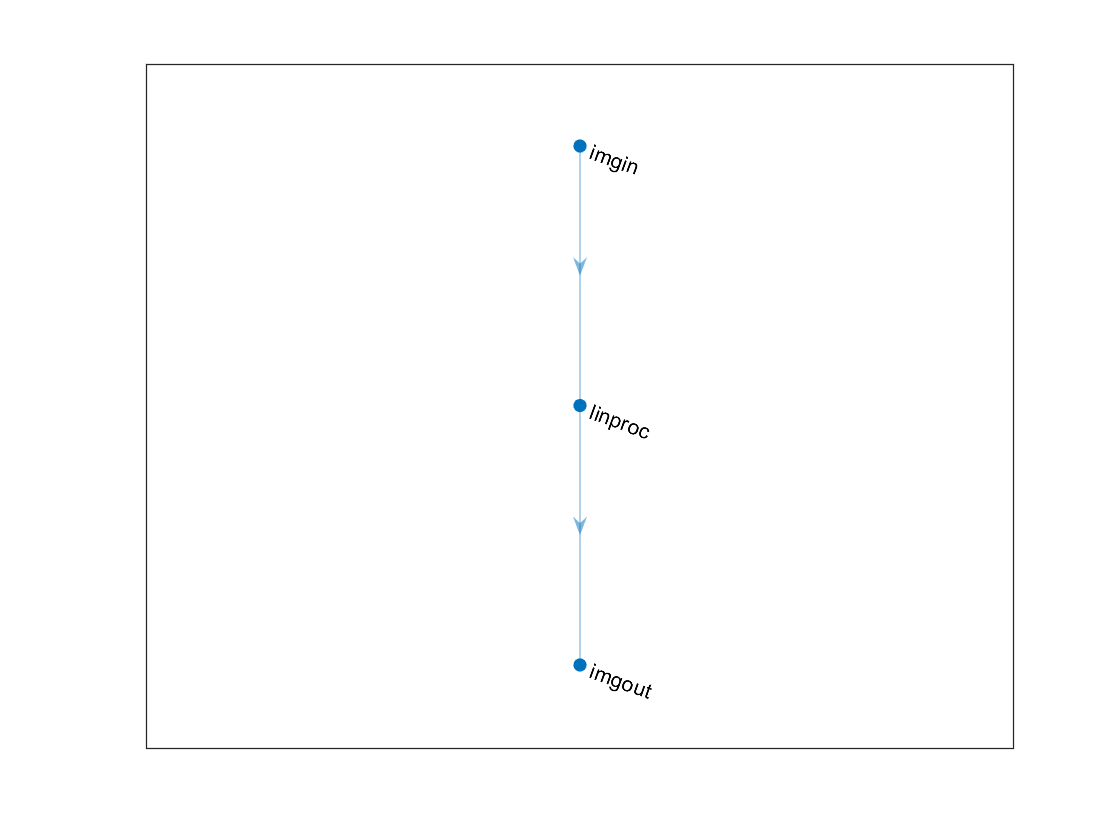

hsize = [9 9];
hsigma = 2;
downfactor = [2 2];
padopt = 'circ';
fwdproclayer = forwardMeasurement2dLayer(...
    'Name','linproc',...
    'Sigma',hsigma,...
    'PsfSize',hsize,...
    'PadOption',padopt,...
    'DecimationFactor',downfactor);
adjproclayer = fwdproclayer.createAdjointLayer();

% Simulation 
proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(size(u),'Name','imgin','Normalization','none'),...
    fwdproclayer,...
    regressionLayer('Name','imgout')]);
plot(proclgraph)

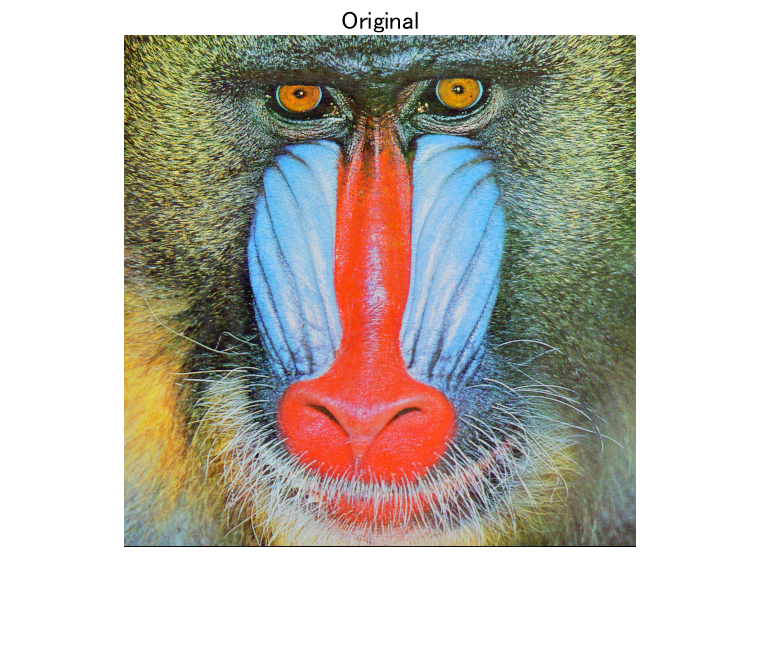

procnet = assembleNetwork(proclgraph);
v = imnoise(procnet.predict(u),'gaussian',0,sgm^2);

%
imshow(u)
title('Original')

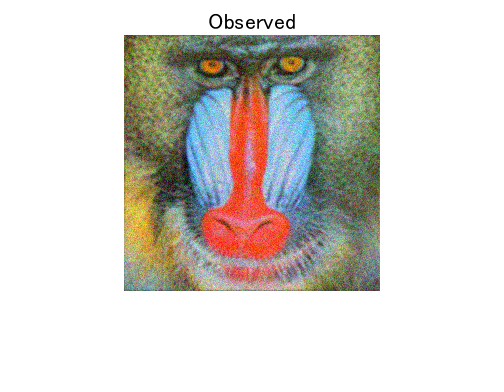

imshow(v)
title('Observed')

### Learned ISTA with Structured Convolutional Dictionary

#### References

- K. Gregor and Y. LeCun, "Learning fast approximations of sparse coding", *Proc. Int. Conf. Machine Learning*, pp. 399-406, 2010.

- V. Monga, Y. Li and Y. C. Eldar, "Algorithm Unrolling: Interpretable, Efficient Deep Learning for Signal and Image Processing," in IEEE Signal Processing Magazine, vol. 38, no. 2, pp. 18-44, March 2021, doi: 10.1109/MSP.2020.3016905.

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\left(\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ +\lambda\|\mathbf{s}_n\|_1\right),$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a dictionary with the design parameter vector $\mathbf{\theta}}$.

#### ISTA

- Initialization: $\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left( \mathbf{s}^{(t)}-\gamma\nabla_\mathbf{s}f(\mathbf{s}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

where

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD_{\mathbf{\theta}}\mathbf{s}-\mathbf{v})$$


- 
$$\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


ISTAのStep 2 は以下のように書くことが出来る。

- 
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma g}\left(\mathbf{s}^{(t)}-\gamma\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD}_{\mathbf{\theta}}\mathbf{s}^{(t)}-\mathbf{v})\right)$$


上記のステップは、等価的に分析・閾値処理・合成の形として以下のように書き換えることも可能である。

#### ISTA 

- Initialization: $\mathbf{s}^{(0)}$, $\mathbf{u}^{(0)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Residual: $\mathbf{r}^{(t)}\leftarrow \mathbf{P}^T(\mathbf{P}\mathbf{u}^{(t)}-\mathbf{v})$

- Analysis process: $\mathbf{y}^{(t)}\leftarrow \mathbf{D}_{\mathbf{\theta}}^T\mathbf{r}^{(t)}$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left(\mathbf{s}^{(t)}-\gamma\mathbf{y}^{(t)}\right)$

- Synthesis process: $\mathbf{u}^{(t+1)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(t+1)}$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

初期化部分は、

- 
$$\mathbf{s}^{(0)}\leftarrow \mathbf{D}^T_{\mathbf{\theta}}\mathbf{P}^T\mathbf{v}\Rightarrow\mathbf{u}^{(0)}\leftarrow \mathbf{P}^T\mathbf{v}$$


と設定できる。

- $\gamma<2/\beta$: Step size

- $\beta$: Lipschitz constant of $\nabla f$, where $\beta = (\sigma_{\mathrm{max}}(\mathbf{PD}))^2$

## Construction of layers

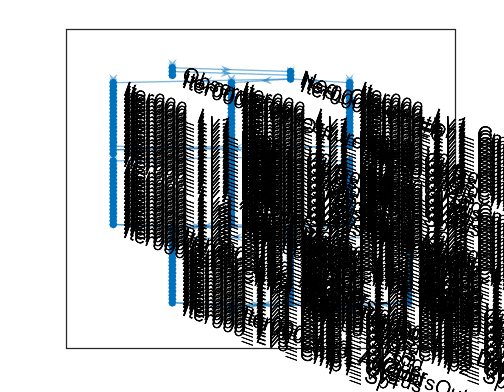

import saivdr.dcnn.*
nComponents = szPatchTrn(3);
%listalgraphs = cell(1,nIters);

% Initialize
strIter = sprintf('Iter%03d_',0);
listalgraph = fcn_creatensoltlgraph2d(...
    'AppendInOutLayers',false,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer',...
    'Prefix',strIter);
imginputlayer0 = imageInputLayer(szPatchTrn./[decFactor 1],'Name','Observation');
adjproclayer0 = adjproclayer;
adjproclayer0.Name = [strIter 'AdjMeasure'];
listalgraph = listalgraph.addLayers(...
    [imginputlayer0,adjproclayer0]);
%
strLv = sprintf('Lv%0d_',1);
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'In']);

% Add intermediate result output
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'Out']));
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'Out']);

% Add Coefs. output
strLv = sprintf('Lv%0d_',nLevels);
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsOut']);
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsOut']);
end

% Add negative process
listalgraph = listalgraph.addLayers(scalingLayer('Name','Neg_Observation','Scale',-1));
listalgraph = listalgraph.connectLayers('Observation','Neg_Observation');

% Plot
plot(listalgraph)

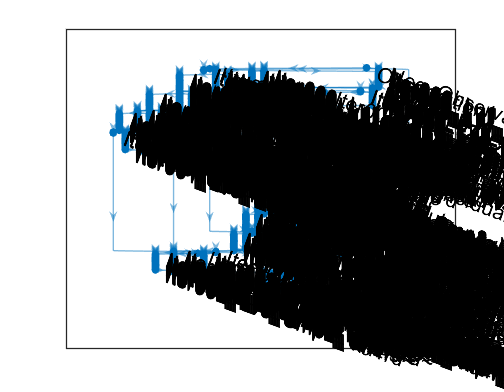

import saivdr.dcnn.*
nComponents = szPatchTrn(3);
% Iteration
for iter = 1:nIters
    strIter = sprintf('Iter%03d_',iter);
    strIterPre = sprintf('Iter%03d_',iter-1);
    
    % Analysis-synthesis system
    nsoltlgraphi = fcn_creatensoltlgraph2d(...
        'AppendInOutLayers',false,...
        'NumberOfComponents',nComponents,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Prefix',strIter);
    for iLayer = 1:height(nsoltlgraphi.Layers)
        layer = nsoltlgraphi.Layers(iLayer);
        listalgraph = listalgraph.addLayers(layer);
    end
    for iConnection = 1:height(nsoltlgraphi.Connections)
        connection = nsoltlgraphi.Connections(iConnection,:);
        listalgraph = listalgraph.connectLayers(connection.Source{1},connection.Destination{1});
    end

    % Measurement processes
    fwdproclayeri = fwdproclayer;
    fwdproclayeri.Name = [strIter 'FwdMeasure'];
    adjproclayeri = adjproclayer;
    adjproclayeri.Name = [strIter 'AdjMeasure'];
    listalgraph = listalgraph.addLayers([fwdproclayeri,additionLayer(2,'Name',[strIter 'Residual']),adjproclayeri]);
    listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter 'Lv1_In']);

    % Analyzer
    strLv = sprintf('Lv%0d_',1);
    listalgraph = listalgraph.replaceLayer([strIter strLv 'In'],...
        scalingLayer('Name',[strIter strLv 'In'],'Scale',-gamma));

    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.disconnectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcIn']);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsIn']));
    listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'DcCoefsResidual']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsResidual/in1']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsIn'],[strIter strLv 'DcCoefsResidual/in2']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcIn']);
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.disconnectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcIn']);
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsIn']));
        listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'AcCoefsResidual']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsResidual/in1']);
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsIn'],[strIter strLv 'AcCoefsResidual/in2']);
    end

    % Synthesizer
    strLvPre = '';
    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    if iter < nIters
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcCoefsOut']);
    end
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        % For AC
        if isLET
            if iLv == nLevels
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',false,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
            else
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',true,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLvPre 'AcTh'],[strIter strLv 'AcTh/parent']);
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh/child']);
            end
        else % Soft-thresholding
            listalgraph = listalgraph.addLayers(...
                sfthLayer('Name',[strIter strLv 'AcTh'],'Lambda',lambda,... % Activation function for AC between Analyzer & Synthesizer
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
        end
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcIn']);
        %
        if iter < nIters
            listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcCoefsOut']);
        end
        %
        strLvPre = strLv;
    end
    
    % Connect iteration stages
    listalgraph = listalgraph.connectLayers([strIterPre 'Lv1_Out'],[strIter 'FwdMeasure']);
    listalgraph = listalgraph.connectLayers('Neg_Observation',[strIter 'Residual/in2']);
    %
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.connectLayers([strIterPre strLv 'DcCoefsOut'],[strIter strLv 'DcCoefsIn']);
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.connectLayers([strIterPre strLv 'AcCoefsOut'],[strIter strLv 'AcCoefsIn']);
    end
end
plot(listalgraph)

strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');

analyzeNetwork(listalgraph);

### Preparation of traning image

Randomly extracting patches from the image data store

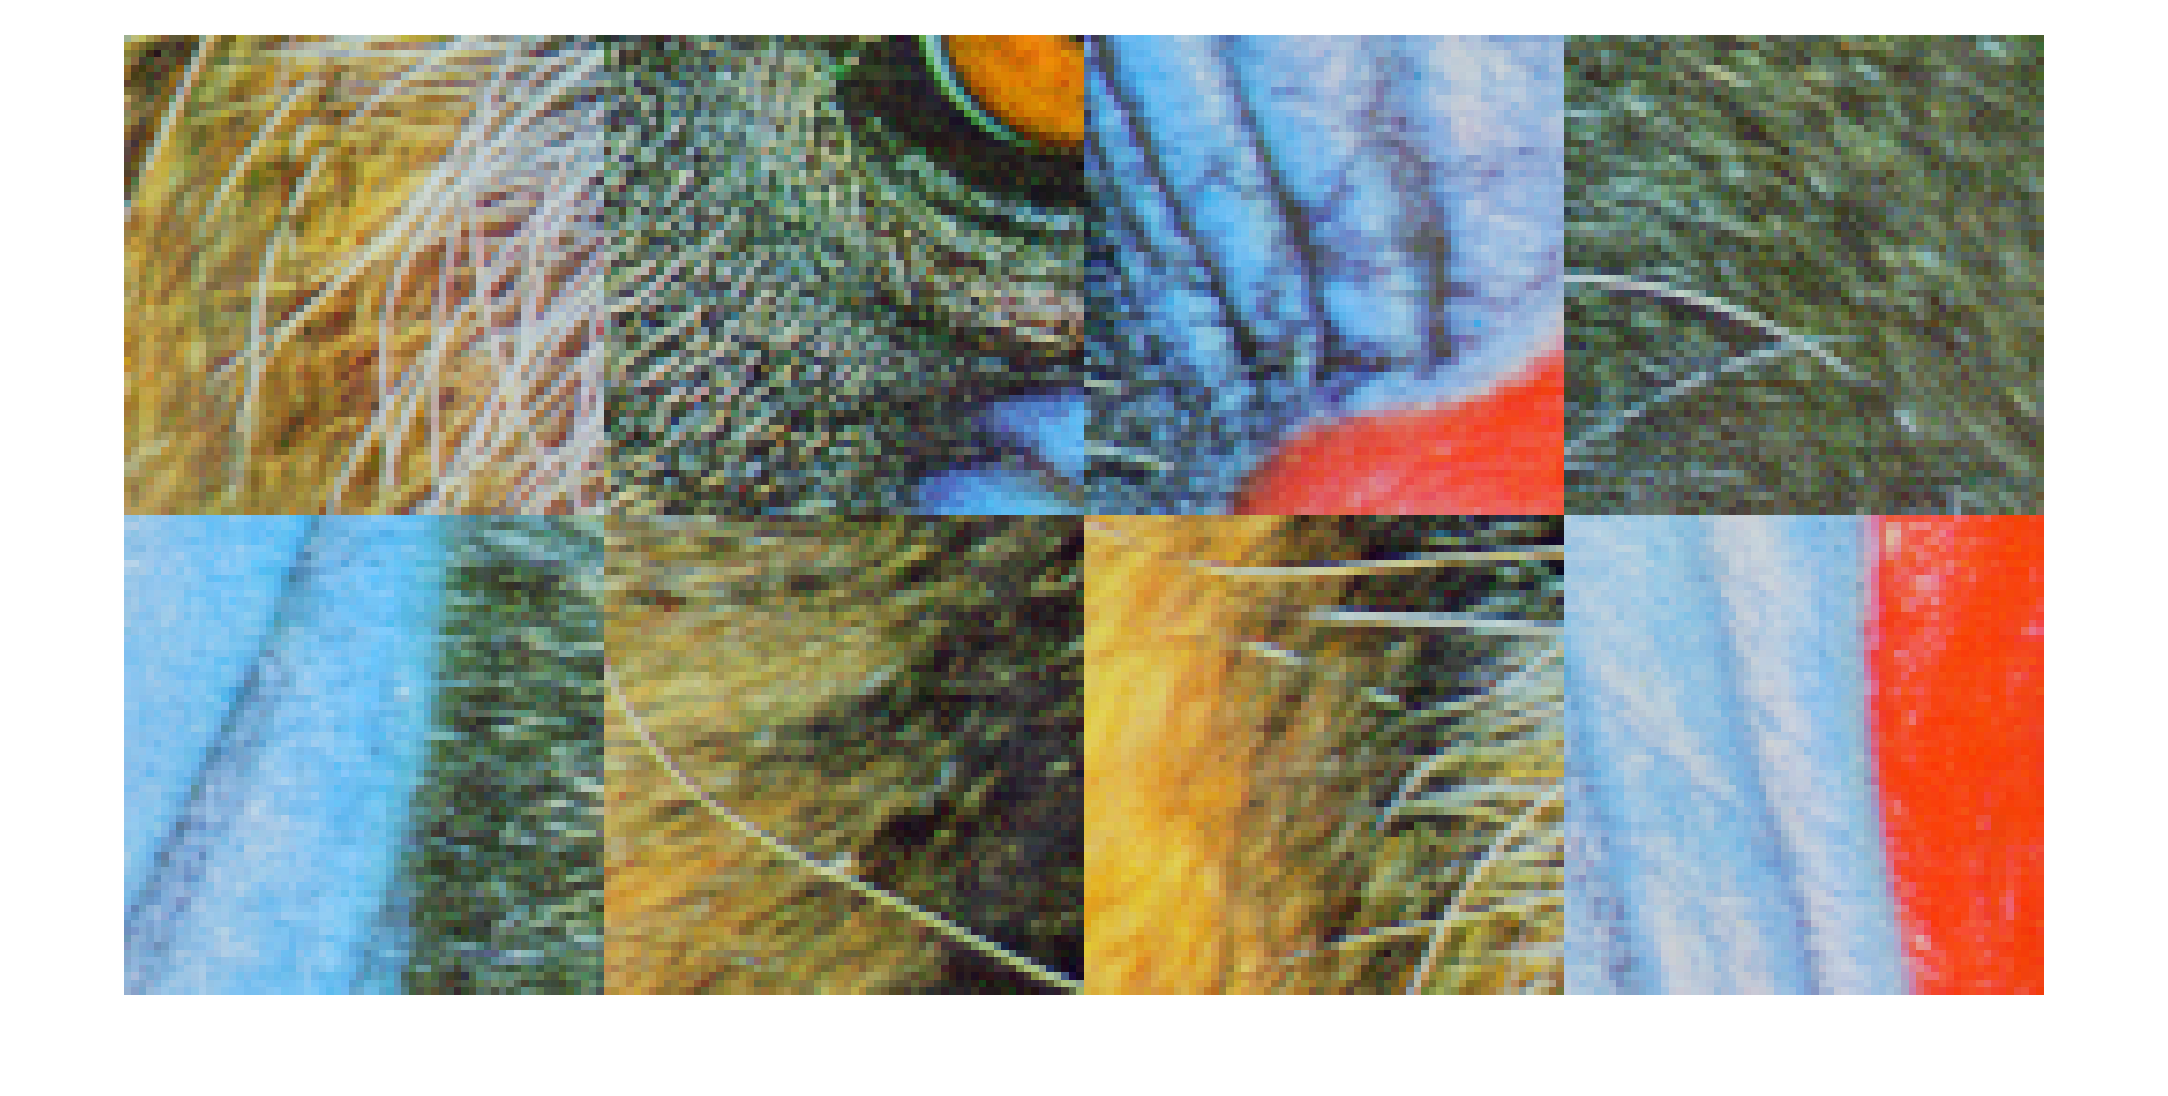

imds = imageDatastore("./data/baboon.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);


% Training options
opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',maxEpochs,...30,...
    'MiniBatchSize',miniBatchSize,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

% Observation 
proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(szPatchTrn./[decFactor 1],'Name','imgin','Normalization','none'),...
    fwdproclayer]);
procnet = dlnetwork(proclgraph);
obsds = transform(patchds, @(x) myobservation(x,procnet,sgm));

% Training 
trainednet = trainNetwork(obsds,listalgraph,opts);

単一の GPU で学習中。
入力データの正規化を初期化しています。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


エラー: trainNetwork (行 184)
学習イメージのサイズは 16×16×3 ですが、入力層にはサイズ 32×32×3 のイメージが必要です。

function newdata = myobservation(oldtbl,procnet,sgm)
% 
restbl = removevars(oldtbl,'InputImage');
dlx = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
dly = procnet.predict(dlx);
dlv = dly + sgm*dlarray(randn(size(dly)),'SSCB');
varray = permute(num2cell(extractdata(dlv),1:3),[4 1 2 3]);
% Output as a cell in order to make multiple-input datastore
newdata = [ varray table2cell(restbl) ];
end